# Deep Learning with MATLAB - Use a Pretrained Deep Neural Network

This demo is an introduction to how to do transfer learning in MATLAB using the Deep Network Designer app.

Based on [https://www.mathworks.com/help/deeplearning/ug/transfer-learning-with-deep-network-designer.html](https://www.mathworks.com/help/deeplearning/ug/transfer-learning-with-deep-network-designer.html) 

The goal is to use the Deep Network classify MathWorks merch instead of the images that ResNet-18 was originally trained on

- Open the Deep Network Designer app and choose a pretrained network.

- Import the new data set.

- Replace the final layers with new layers adapted to the new data set.

- Set learning rates so that learning is faster in the new layers than in the transferred layers.

- Train the network using Deep Network Designer, or export the network for training at the command line.

To open Deep Network Designer, run

deepNetworkDesigner

trainInfoStruct_1 = struct with fields:
               TrainingLoss: [1×40 double]
           TrainingAccuracy: [1×40 double]
             ValidationLoss: [1×40 double]
         ValidationAccuracy: [60 NaN NaN NaN 90 NaN NaN NaN NaN 90 NaN NaN NaN NaN 95 NaN NaN NaN NaN 95 NaN NaN NaN NaN 90 NaN NaN NaN NaN 95 NaN NaN NaN NaN 95 NaN NaN NaN NaN 95]
              BaseLearnRate: [1×40 double]
        FinalValidationLoss: 0.2004485
    FinalValidationAccuracy: 90


or on the **Apps** tab, under **Machine Learning and Deep Learning**, click the app icon.

## Select pretrained network

Let's choose the ResNet-18 network from the provided neural networks. If you do not have it, you can install it.

### Explore Network

Deep Network Designer displays a zoomed-out view of the whole network in the **Designer** pane.

You can zoom in, click on layers etc. to get a feel for the network's architecture.

## Import Data

To load the data into Deep Network Designer, on the **Data** tab, click **Import Data**.

In the **Data source** list, select **Folder**. Click **Browse** and select the MerchData folder.

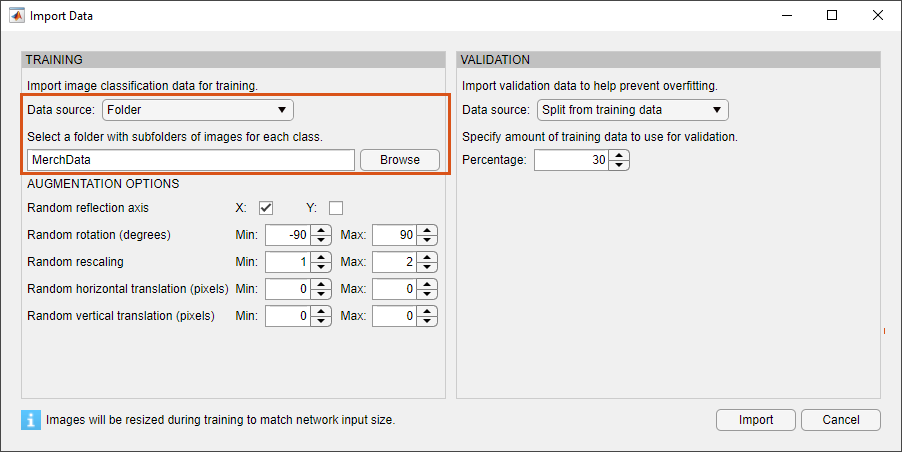

### Image Augmentation

If you want to, you can perform image augmentation inside the Deep Network Designer app. Let's do random reflections in the x-axis, random rescaling in the range [1,2], and random rotations in the range [-90,90]

This effectively increases the amount of training data while also enables you to train networks to be invariant to distortions in image data. For example, you can add randomized rotations to input images so that a network is invariant to the presence of rotation in input images. 

For this example, apply a random reflection in the x-axis, a random rotation from the range [-90,90] degrees, and a random rescaling from the range [1,2].

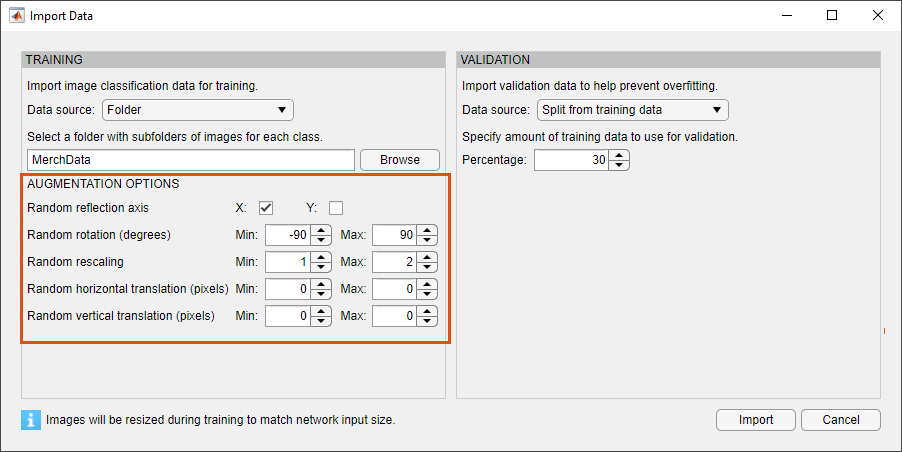

### Validation Data

Validation estimates model performance on new data compared to the training data, and helps you to monitor performance and protect against overfitting. Let's use 30% of the images for validation.

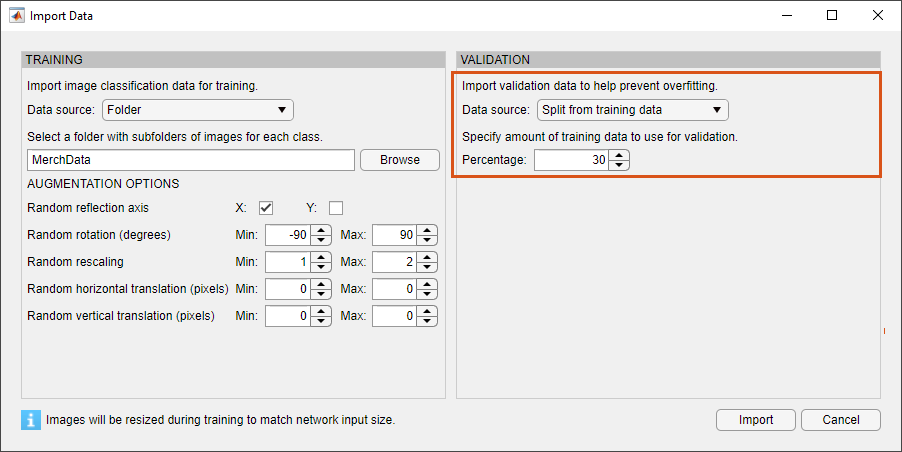

Click **Import** to import the data into Deep Network Designer. 

This will show a plot of the different classes.

## Prepare Network for Training

Edit the network in the **Designer** pane to specify a new number of classes in your data. To prepare the network for transfer learning, replace the last learnable layer and the final classification layer. 

### Replace Last Learnable Layer

To use a pretrained network for transfer learning, you must change the number of classes to match your new data set. First, find the last learnable layer in the network. For ResNet-18, this is fc1000. Replace this with a new fully connected layer with the output size of 5.

Change the learning rates so that learning is faster in the new layer than in the transferred layers by setting set `WeightLearnRateFactor` and `BiasLearnRateFactor` to 10.

### Replace Output Layer

For transfer learning, you need to replace the output layer. Scroll to the end of the **Layer Library** and drag a new `classificationLayer` onto the canvas. Delete the original `output` layer and connect your new layer in its place. 

At training time, Deep Network Designer automatically sets the output classes of the layer from the data.

### Check Network

To check that the network is ready for training, click **Analyze**. If the Deep Learning Network Analyzer reports zero errors, then the edited network is ready for training.

## Train Network

The Deep Network Designer app enables you to train image classification networks imported or created in the app. For other types of data, you can construct the network in Deep Network Designer and then export the network for training (see e.g., "[Create Simple Sequence Classification Network Using Deep Network Designer](docid:nnet_ug#mw_f9693b8c-fb23-498c-af16-e32e52926906)").

To train the network with the default settings, on the **Training** tab, click **Train**. The default training options are better suited for large data sets, for small data sets reduce `MiniBatchSize` and `ValidationFrequency`. 

If you want greater control over the training, click **Training Options** and choose the settings to train with. 

- Set solver to `adam` (optional)

- Set `InitialLearnRate` to a small value to slow down learning in the transferred layers.

- Specify `ValidationFrequency` so that the accuracy on the validation data is calculated once every epoch.

- Specify a small number of epochs. An epoch is a full training cycle on the entire training data set. For transfer learning, you do not need to train for as many epochs.

- Specify the mini-batch size, that is, how many images to use in each iteration. To ensure the whole data set is used during each epoch, set the mini-batch size to evenly divide the number of training samples.

For this example, set `InitialLearnRate` to `0.0001`, `ValidationFrequency` to `5`, `MaxEpochs` to 3, and Solver to `adam` (optional). As there are 55 observations, set `MiniBatchSize` to 11 to divide the training data evenly and ensure you use the whole data set during each epoch. For more information on selecting training options, see [`trainingOptions`](docid:nnet_ref#bu59f0q). 

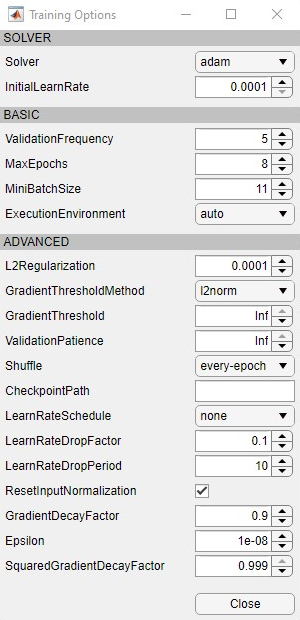

To train the network with the specified training options, click **Close** and then click **Train**.

Deep Network Designer will visualize the training progress.

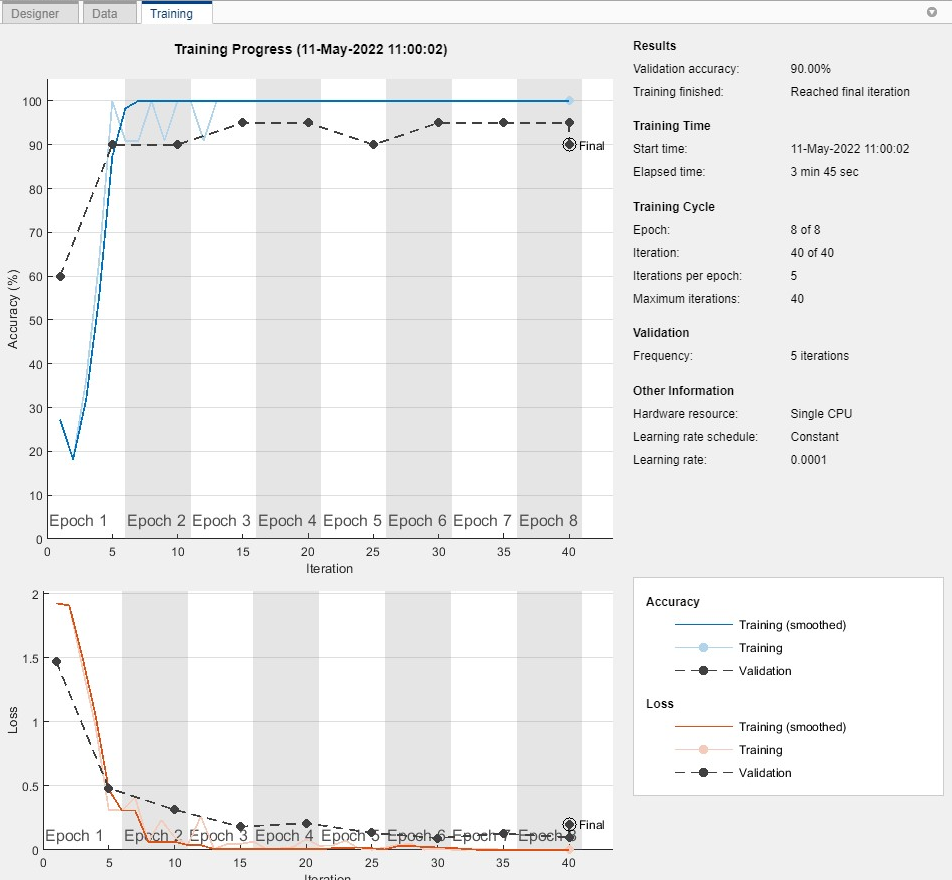

## Export Results and Generate MATLAB Code

To export the network architecture with the trained weights, on the **Training** tab, select **Export > Export Trained Network and Results**. Deep Network Designer exports the trained network as the variable `trainedNetwork_1` and the training info as the variable `trainInfoStruct_1`. 

trainInfoStruct_1

You can also generate MATLAB code, which recreates the network and the training options used.

## Classify New Image

Load a new image to classify using the trained network.

test_image = imread("test_torch.JPG");

Deep Network Designer resizes the images during training to match the network input size.

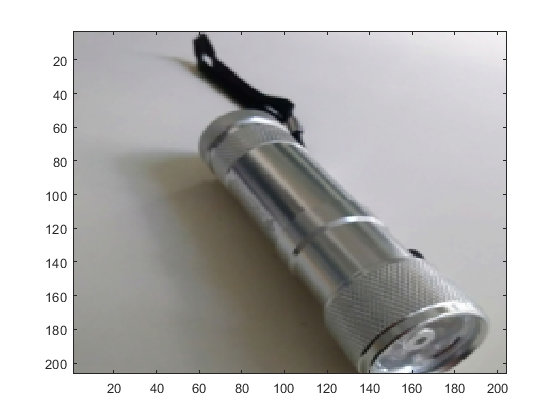

I = imresize(test_image, trainedNetwork_1.Layers(1).InputSize(1:2));
image(I)

Classify the test image using the trained network.

[label, scores] = classify(trainedNetwork_1,I);
label

label = categorical
     MathWorks Torch 


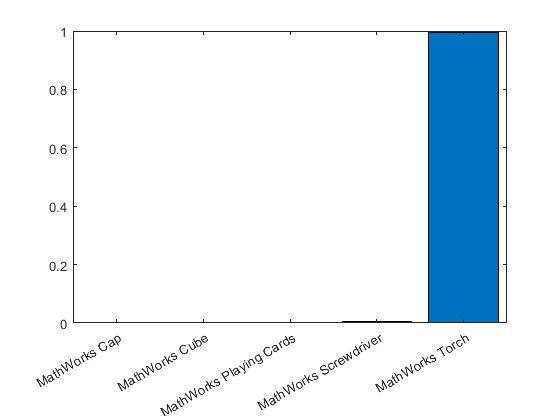

figure;
bar(trainedNetwork_1.Layers(end).Classes, scores)

It works well!